## Covid-19 Cough Sound Classification (Covid-19 Öksürük Sesleri Sınıflandırması)

Öksürük sesleri akciğer sesleri ile birlikte solunum hastalıklarında önemli bir ön tanı aracıdır. Öksürük, akciğerlerden havanın sıpazmodik bir şekilde çıkması olarak tanımlanır. Tipi ve şiddeti hastalığın seyrine, hastalığın tipine ve akciğerlere verdiği zarara göre değişir. Öksürük, üst solunum yolları ile alakalı olabileceği gibi alt solunum yolları ile de alakalı olabilir. [[öksürük](https://en.wikipedia.org/wiki/Cough)]

Koronavirüs hastalığı (COVID 19) şiddetli akut solunum yolu sendromuna yol açan, Çin'in Wuhan şehrinde ilk defa ortaya çıkmış bulaşıcı bir hastalıktır. Semptomları arasında ateş, öksürük, nefes darlığı ve diğer solunum sıkıntıları bulunmaktadır. Özellikle vakaların %80'inden fazlasında yüksek ateş ve öksürük başlıcak semptomdur. [[Dünya Sağlık Örügütü Raporu](https://www.who.int/docs/default-source/coronaviruse/who-china-joint-mission-on-covid-19-final-report.pdf)]

Özellikle yüksek ateş kolay ölçülebilen bir bulgu olduğu için koronavirüs hastalığına yakalanan insanların toplumdan ayırılmasında kullanılmaktadır. Ancak bir diğer yaygın belirti olan öksürük konusunda yaygın kullanılan ve kabul edilmiş herhangi bir teknoloji geliştirilmemiştir. Koronavirüs hastalığının sebep olduğu öksürük diğer hastalıkların sebep olduğu öksürükten oldukça faklı bir sinyal yapısında sahiptir. Bu konuda, çalışmalar yapılmakta ve bütün dünyadan öksürük sesleri toplanmaya başlanmıştır. [[EPFL Çalışması](https://coughvid.epfl.ch/)] [[University of Cambridge Çalışması](https://www.covid-19-sounds.org/en/)]

Sars-Cov-2 virüsü alt ve üst solunum yollarına zarar vermektedir. Bu zarar özellikle kuru öksürüğe yol açmaktadır. Kuru öksürük içinde mukus olmayan öksürük demektir. Mukuslu (ıslak) öksürüğün sebebi genellikle alerji, grip veya nezledir. Dolayısıyla Sars-Cov-2 virüsünün sebep olduğu öksürüğü ayırabilme şansımız vardır. Şu çalışmalar [[çalışma 1](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0162128)] [[çalışma 2](https://ieeexplore.ieee.org/document/7311223)] zatüree gibi hastalıkları daha önce öksürük sesiyle ayırt etmiştir ve yüksek doğruluk oranına ulaşmışlardır.

Ben Boğaziçi Üniversitesi'nde Elektrik Elektronik Mühendisliği yüksek lisans öğrencisiyim. Akciğer sesleri laboratuvarında çalışmaktayım. Tezimi ise hırıltı seslerinin (Wheeze) normal akciğer seslerinden ayrıştırılması ve işaretlenmesi üzerine yazıyorum. Bu çalışmada daha önce wheeze seslerine uyguladığımız teknikleri öksürük seslerine uygulayarak geliştirdim.

Bu çalışmanın ilk amacı Covid-19'lu hastaların öksürük seslerini diğer hastaların öksürük seslerinden ayırmaktır.

### DATASET

Datasetimde internette bulduğum ses dosyalarından oluşturdum. Üç tane koronavirüs hastasının videosunu buldum. Bunlar:

[Covid 19 öksürük sesi 1](https://www.youtube.com/watch?v=CMmsscVN-js) (3-6 saniyeleri) ve (67 - 70 saniyeleri)

[Covid 19 öksürük sesi 2](https://www.youtube.com/watch?v=GwFmk6PgmqI) (8 - 12 saniye arasında)

[Covid 19 öksürük sesi 3](https://www.youtube.com/watch?v=EZxcEljV6WA) (Bir çok yerde)

[Normal öksürük sesi 1](https://www.youtube.com/watch?v=i_hI3gVoRr0&t=63s) (Bir çok kişiden, Video mayıs 2018 tarihli olduğu için hiçbir öksürük koronavirüsün sebepli değil.)

Bu videoların sadece seslerini alarak, öksürük olan ses parçalarını kestim. Elimde 30 saniyelik KoronaVirüs hastalığı öksürüğü oldu. Normal öksürüklerden de 30 saniyelik öksürük sesini kestim. Böylece toplam 60 saniyelelik ses datası oluşturdum.

### DATASET HAZIRLANMASI

DataSetimdeki ses parçaları 44100 sample rate'ine 16 bit sample çözünürlüğüne sahiptir. Herbir ses parçasını %25 overlap ile 1024 sample'lık normal windowlara böldüm. Herbir window yakşalık 23 ms'dır. Bu da feature extaction için yeterli bir uzunluktur. Daha sonra herbir window'un ana ses içerisindeki indislerini, hangi öksürük videosuna ait olduğunu ve label'ını bir table içerisinde topladım. Matlab'da aşağıdaki koddan datasetini yükleyip inceleyebilirsiniz.

Raw Seslerinin bulunduğu dataSet:

clc;
clear;

addpath('functions');

addpath('dataSets');


load('coughSet.mat')
sound(dataSet(6).SoundData,44100);

Windowlanmış seslerin bulunduğu dataSet:

load('windowedCoughSet.mat');

disp("length of windows: "+length(dataSet));

length of windows: 2201


Görüldüğü gibi dataSetimde 2201 tane window bulunmaktadır. Bu windowindowlardan 955 tanesi Covid öksürük (1) olarak işaretlenmiş, geri kalan 1246 tanesi normal öksürük (0) olarak işaretlenmiştir.

### FEATURE SET HAZIRLANMASI

Öksürük seslerinin ayrıştırılmasında kullandığım featureları daha önce hastalıklı akciğer seslerinin ayrıştırılmasında kullanılan ve başarılı sonuçlar veren feature'lar arasından seçtim. Bu makalede wheeze seslerinin ayrıştıran feature'ları karşılaştırmışlar. Bu feature'lardan da yararlandım. Bunlar:

- Kurtosis

- Renyi Entropies with order 1,2, and 3

- Percentile Frequency Ratios (f25/f75, f25/f90, f50/f90, f50/f75)

- Mean Crossing Irregularity

- AR Parameters (Yule-Walker -> LPC Paramters)

- Mell Frequency Cepstral Coefficients

- Tonality Index

Bu featurelar akciğer seslerinin ayrıştırılmasında kendini kanıtlamış ses hesaplama özellikleridir. Ayrıca çoğu konuşma algılama alanında da kullanılmaktadır. Bu feature'ların herbirinin ayrıntısına ve hesaplama yöntemine bu çalışmada değinmeyeceğim. Zaten çoğunun hesaplanmasına internetten ulaşabilirsiniz. Ancak bunların hepsini ve daha fazlasını akciğer seslerinde hırıltı (wheeze) algılama algoritmasında kullandım. Tezimde her bir özelliği ayrı ayrı açıkladım ve hesaplama algorirmalarını verdim. Tezimin bu bölümünü bu klasöre ekledim.

% Kurtosis
dataSet=findKurtosis(dataSet);
disp("Kurtosis is finished.");

Kurtosis is finished.


% F25/F75
dataSet=Ratio_of_25_to_75(dataSet);
disp("F25/F75 is finished.");

F25/F75 is finished.


% F25/F90
dataSet=Ratio_of_25_to_90(dataSet);
disp("F25/F90 is finished.");

F25/F90 is finished.


% F50/F75
dataSet=Ratio_of_50_to_75(dataSet);
disp("F50/F75 is finished.");

F50/F75 is finished.


% F50/F90
dataSet=Ratio_of_50_to_90(dataSet);
disp("F50/F90 is finished.");

F50/F90 is finished.


% Mean Crossing Irregularity
dataSet=calcZeroCrIr(dataSet);
disp("Mean Crossing Irr is finished.");

Mean Crossing Irr is finished.


% AutoRegressive Parameters
dataSet = ArCalc(dataSet);
disp("AR parameters is finished.");

AR parameters is finished.


% Tonality Index
dataSet = tonalityCalc(dataSet);
disp("TonalityIndex is finished.");

TonalityIndex is finished.


% MFCC
dataSet = calcMFCC(dataSet);
disp("MFCC is finished.");

MFCC is finished.


% Renyi Entropy
dataSet = calcRenyiEntropy(dataSet);
disp("Renyi is finished.");

Renyi is finished.


disp("All is well");

All is well


Data set'i training için hazır hale getirdim.

% Training için hazırlama
T = struct2table(dataSet);
T = removevars(T, 'winSound');
T = removevars(T, 'winInds');
T = removevars(T, 'tonalMag');
T = removevars(T, 'phi_sav');
T = removevars(T, {'cm','energy','spectUnPred'});
T(1:2,:) = [];
T.TI = cell2mat(T.TI);
[row, col] = find(isnan(T{:,:}));
T(row,:) = [];
isCovid = [T.label];
T(isCovid == 1,12) = {'covid'};

T(isCovid == 0,12) = {'normal'};
T.Properties.VariableNames{12} = 'isCovid';
T = movevars(T, 'isCovid', 'Before', 'kurtosis');
T = splitvars(T, 'renyi');
T = splitvars(T, 'ArParams');
T.Properties.VariableNames{15} = 'Ar_Error';
T = splitvars(T, 'MFCCParams');

### CLASSIFIER SEÇİMİ

Yukarıdaki hesaplamaları yaptıktan sorna feature table'ımda 34 tane sütun oluştu. Herbir sütun farklı özellikleri ifade etmektedir.

Bu training set ile denediğim classiferlar şunlardır:

- KNN (k = 9)

- Linear SVM (C=1)

- Poynomial SVM order 3 (C = 1, Kernel Scale = 4.7)

- Gaussian SVM (C = 1, Kernel Scale = 2.5)

- Maximum Likelihood with Multivariate Gaussian

- Binary Decision Tree (max numb of splits: 100 ve Gini's diversity index)

Bütün sınıflandırıcılar ile data sayımız düşük olduğu için 5-fold cross validation yapıldı. Performansları karşılaştırıldı. Binary Decision Tree en iyi sonucu veren sınıflandırıcı oldu.

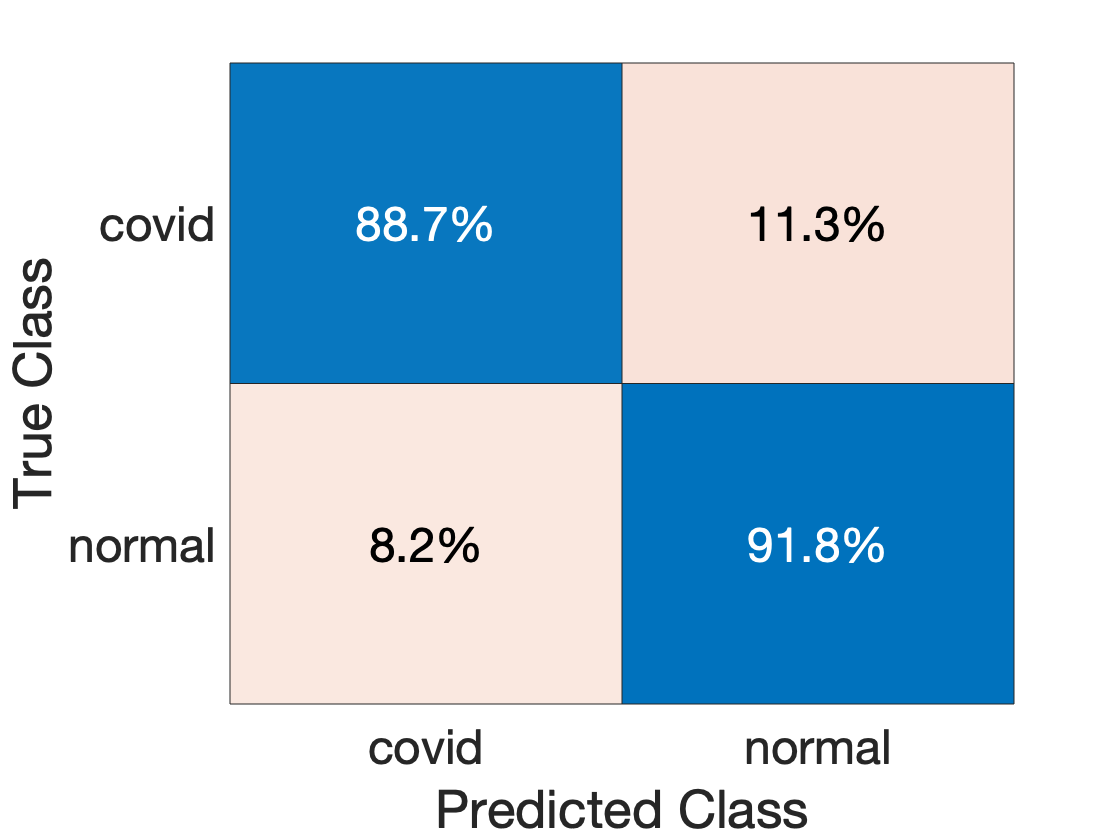

randoms = randperm(size(T,1));

X_label = T(:,2);
X = T(:,3:end);

X_train = X(randoms(1:size(T,1)),1:end);
X_train_label = table2cell( X_label(randoms(1:size(T,1)),1));

% Model
classificationTree = fitctree(...
    X_train, ...
    X_train_label, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 100, ...
    'Surrogate', 'off', ...
    'ClassNames', {'covid'; 'normal'});

% Performance
partitionedModel = crossval(classificationTree, 'KFold', 5);

[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

validationAccuracy = sum(strcmp(classificationTree.Y, validationPredictions))/length(validationPredictions);

confmat=confusionmat(classificationTree.Y,validationPredictions);

k = confusionchart(classificationTree.Y,validationPredictions,'Normalization','row-normalized','FontSize',24);
sortClasses(k,["covid","normal"])


disp("accuracy: "+validationAccuracy+"%");

accuracy: 0.90401%



TP = confmat(2,2);
FP = confmat(2,1);
FN = confmat(1,2);
TN = confmat(1,1);

disp("Sensivity: "+TP/(TP+FN)+"%");

Sensivity: 0.89418%


disp("Specificity: "+TN/(TN+FP)+"%");

Specificity: 0.91162%


disp("F1Ratio: "+2*TP/(2*TP+FN+FP));

F1Ratio: 0.89041


Sonuçlardan anlaşılacağı gibi %90 doğruluk oranı ile covid19 içeren windowları işaretlemiş olduk. Ayrıca model sadece covid'li öksürükleri %88 oranında doğru tesbit etti. Ancak SVM ve KNN'de çıkan düşük sonuçlar, Binary classifer'a olan güveni düşürüyor. DataSetimizin az sayıda olması bu çarpıklığı açıklayabilir ve Tree fazla eğitilmiş olabilir. Ancak aşağıdaki grafik covid'li öksürük ile diğer öksürükleri ayrılabileceğini gösteriyor. Grafik MFCC değerleri arasında çıkarılmıştır.

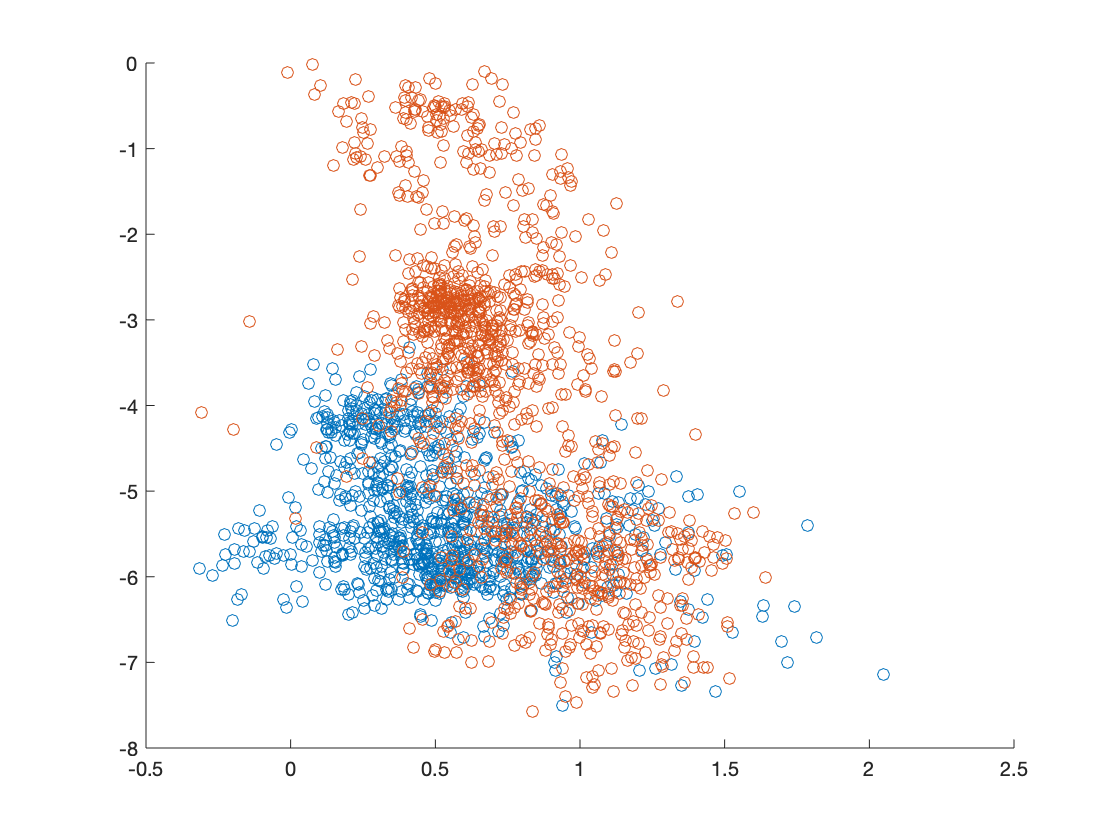

isCovid = [T.label]';
featureCovid = [T(isCovid == 1,:).MFCCParams_10 T(isCovid == 1,:).MFCCParams_4];
featureNonCovid = [T(isCovid == 0,:).MFCCParams_10 T(isCovid == 0,:).MFCCParams_4];

clf
scatter(featureCovid(:,1),featureCovid(:,2)); hold on; scatter(featureNonCovid(:,1),featureNonCovid(:,2))

### EN İYİ FEATURE

Toplam 8 Feature ile eğittiğimiz sınıflandırıcı için hangi feature'ların daha ayırıcı olduğunu sorguladım. Bunun için Forward Feature Selection tekniğini denedim ve sonuçlar şu şekilde oldu.

X_label = T(:,1);
X_train_label = X_label(randoms(1:size(T,1)),1);


%% FORWARD
opts = statset('display','iter');
 
classf = @(train_data, train_labels, test_data, test_labels)...
     sum(...
     predict(...
     fitctree(...
     train_data, ...
     train_labels, ...
     'SplitCriterion', 'gdi', ...
     'MaxNumSplits', 100, ...
     'Surrogate', 'off', ...
     'ClassNames', [0; 1])...
     ,test_data) ~= test_labels);
 
[fs, history] = sequentialfs(classf, X_train{:,:}, X_train_label{:,:}, 'cv', c, 'options', opts,'direction','forward');

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 18, criterion value 0.252884
Step 2, added column 24, criterion value 0.18228
Step 3, added column 14, criterion value 0.134287
Step 4, added column 19, criterion value 0.109368
Step 5, added column 22, criterion value 0.0904476
Step 6, added column 23, criterion value 0.0835256
Step 7, added column 25, criterion value 0.0793724
Final columns included:  14 18 19 22 23 24 25 


Sonuçlardan görüldüğü gibi en ayırt edici feature tahmin edildiği gibi Mell Frequency Cepstral'dan 4 ve 10'uncu coefficientlar olmuştur. Sonra da Tonality index gelmektedir. Tonality Index ve MFCC birlikte 92,1% doğruluk oranına ulaşmaktadır.

### Öksürük Sesi Örneğinden Covid Teşhisi

Son olarak 5 saniyelik bir öksürük sesinin covid'li olup olmadığına karar vermek için aşağıdaki algoritma izlenebilir.

- Öksürük Sesi 24 ms'llık windowlara ayrılır. (1024 samples 25% overlap)

- Her bir windo için feature hesaplaması yapılır.

- Sonra windowlar bu modelle tahmin edilerek labellanır.

- Burada ufak bir treshold konularak Covid sonucu söylenir. (Örneğin windowların %80'ininden fazlası Covid positif ise öksürük Covid'lidir. )

Bu testleri elimde yeterli öksürük verisi olmasığı için yapamadım.

### Sonuçlar Üzerine

Bu çalışma öksürük seslerinden Koronavirüs'ü hastalığı teşhisi konusunda umut vaat etmektedir. Sesler bizim bildiğimizden çok daha fazla data barındırır. Yapay öğrenme algoritmaları bu seslerin ayırıcı özellikleri kulağımızdan çok daha iyi ayırır. Eğer bu yapay öğrenme modeli yeni datalar ile geliştirilirse koronavirüs testi ses ile yapılabilir. Ateş gibi datalar ile birliştirilirse de çok daha iyi sonuçlar verebilir.

Bu çalışmanın bir sonraki aşamasında diğer ülkelerde olduğu gibi akıllı telefondan ve bilgisayarlardan öksürük sesi kaydı alınabilir. Daha verimli ve doğruluk oranı yüksek modeller üretilebilir.